cla 

bagselect =rosbag("2025-2-15-22-24-53.bag")

bagselect =   BagSelection with properties:

           FilePath: 'C:\Users\krims\Documents\MATLAB\2025-2-15-22-24-53.bag'
          StartTime: 1.7282e+09
            EndTime: 1.7282e+09
        NumMessages: 119
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [119×4 table]



bSel = select(bagselect,'Topic','/gps_driver2/gps_data');
msgStructs = readMessages(bSel,'DataFormat','struct');
msgStructs{1}

ans = struct with fields:
    MessageType: 'gps_driver2/Customgps'
         Header: [1×1 struct]
       Latitude: 42.3373
      Longitude: -71.0896
       Altitude: 18
     UtmEasting: 3.2786e+05
    UtmNorthing: 4.6893e+06
        UtmZone: 19
      UtmLetter: 'T'
           Hdop: 1.0200
      GpggaRead: '$GPGGA,022454.000,4220.2370,N,07105.3761,W,1,9,1.02,18.0,M,-33.8,M,,0000*5F'


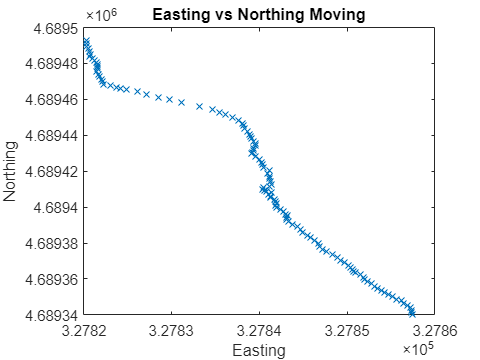




xPoints = cellfun(@(m) double(m.UtmEasting),msgStructs);
yPoints = cellfun(@(m) double(m.UtmNorthing),msgStructs);
plot(xPoints,yPoints,'x')
title('Easting vs Northing Moving')
xlabel('Easting')
ylabel('Northing')

legend hide

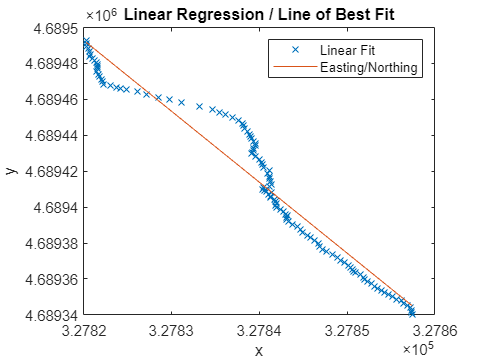


coefficients = polyfit(xPoints, yPoints, 1); 
a = coefficients(1); 
y_fit = polyval(coefficients, xPoints); 

figure; 
plot(xPoints, yPoints, 'x', 'DisplayName', 'Data Points'); % Original data points 
hold on; 

plot(xPoints, y_fit, '-', 'DisplayName', 'Line of Best Fit'); % Line of best fit 

xlabel('x'); 
ylabel('y'); 
title('Linear Regression / Line of Best Fit'); 
legend ('Linear Fit','Easting/Northing');



% mdl = fitlm(xPoints,yPoints)


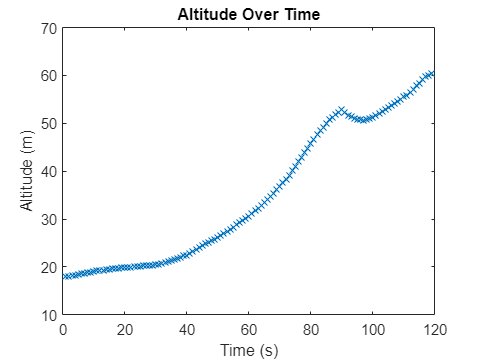

cla 

AltitudeMoving = cellfun(@(m) double(m.Altitude),msgStructs);

plot(AltitudeMoving,'x')
hold on;
title('Altitude Over Time')
xlabel('Time (s)')
ylabel('Altitude (m)')

legend hide
